# add deg2utm to path

addpath('deg2utm/');

## Read data

clear;
clc;
close all;
bagname = 'bag3';
acc_gyro = csvread(strcat(bagname, '/accel_gyro.csv'));
gps = csvread(strcat(bagname, '/gps.csv'));
orientation = csvread(strcat(bagname, '/orentation.csv'));
velocity = csvread(strcat(bagname, '/velocity.csv'));

## Mapping IMU and GPS time stamps

orientation(:, 2:end) = orientation(:, 2:end)*pi/180;
initial_LatLong = [gps(1, 2), gps(1, 3)];
initial_altitude = -gps(1, 4);
initial_roll = orientation(1, 2);
initial_pitch = orientation(1, 3);
initial_yaw = orientation(1, 4);

[initial_easting, initial_northing, ~] = deg2utm(initial_LatLong(1),... 
                                                 initial_LatLong(2));

NEDRPY = [];
for i=1:length(gps)
    [e, n, ~] = deg2utm(gps(i, 2), gps(i, 3));
    o = orientation(i, 2:4);
    time_stamp = gps(i, 1);
    d = -gps(i, 4);
    nedrpy = [n, e, d, o];
    NEDRPY = [NEDRPY; nedrpy];
end

ts_gps = gps(:, 1);
ts_i = 0;

no_of_ts = length(acc_gyro);
time_stamp_map = [];
for i=1:no_of_ts
    ts = acc_gyro(i, 1);
    row_idx_acc = find(ts_gps < ts);
    time_stamp_map = [time_stamp_map; i, row_idx_acc(end)];
end

## State Estimation

State Vector is defined as X, Y, Vx, Vy, Yaw in the Navigation frame

stateVector = zeros(9, 1);
stateVector(1) = initial_northing;
stateVector(2) = initial_easting;
stateVector(3) = initial_altitude;
stateVector(4) = 0;
stateVector(5) = 0;
stateVector(6) = initial_roll;
stateVector(8) = initial_pitch;
stateVector(9) = initial_yaw;

dt_imu = 0.02;

P = zeros(9, 9);
Q = diag([10, 10, 10, 10, 10, 10]); % 6 inputs
R = diag([0.25, 0.25, 1, 1, 1, 1]); % 5 measurements [N E Roll Pitch Yaw]

H = [1 zeros(1, 8);
     0, 1, zeros(1, 7);
     0, 0, 1, zeros(1, 6);
     zeros(1, 6), 1, zeros(1, 2);
     zeros(1, 7), 1, 0;
     zeros(1, 8), 1];
 
gps_idx = 2;
NED_estimated = [initial_northing, initial_easting, initial_altitude];
RPY_estimated = [initial_roll, initial_pitch, initial_yaw];
VNED_estimated = [];
t0 = gps(1,1);
for i = 1:no_of_ts
    dt_imu = acc_gyro(i, 1) - t0;
    phi = stateVector(6);
    theta = stateVector(7);
    psi = stateVector(8);
    Rotx = rotx(phi);
    Roty = roty(theta);
    Rotz = rotz(psi);
    Rotn = Rotz*Roty*Rotx;
    E = [cos(theta)*cos(psi) -sin(psi) 0;
         cos(theta)*sin(psi)  cos(psi) 0;
         -sin(theta) 0 1];
    Einv = inv(E);
    pqr = [acc_gyro(i, 5);
           acc_gyro(i, 6);
           acc_gyro(i, 7)];
    u_dot = Einv*pqr;
    
    aBody = [acc_gyro(i, 2);
             acc_gyro(i, 3);
             acc_gyro(i, 4)];
    
    u_k = [aBody; u_dot];
    [stateVector, P] = motion_model(stateVector, u_k, P, Q, dt_imu);
    if mod(i, 10) == 1 && i ~=1
        if gps_idx <= length(NEDRPY)
            z = [NEDRPY(gps_idx, 1);
                 NEDRPY(gps_idx, 2);
                 NEDRPY(gps_idx, 3);
                 NEDRPY(gps_idx, 4);
                 NEDRPY(gps_idx, 5);
                 NEDRPY(gps_idx, 6)];
            innovation = z - H*stateVector;
            S = H*P*H' + R;
            K = P*H'*inv(S);
            stateVector = stateVector + K*innovation;
            P = P - K*H*P;
            P = 0.5 * (P + P');
            gps_idx = gps_idx+1;
            stateVector(7) = atan2(sin(stateVector(7)), cos(stateVector(7)));
            stateVector(8) = atan2(sin(stateVector(8)), cos(stateVector(8)));
            stateVector(9) = atan2(sin(stateVector(9)), cos(stateVector(9)));
        end
    end

    NED_estimated = [NED_estimated; stateVector(1), stateVector(2), stateVector(3)];
    VNED_estimated = [VNED_estimated; stateVector(4), stateVector(5), stateVector(6)];
    RPY_estimated = [RPY_estimated; stateVector(7), stateVector(8), stateVector(9)];
    t0 = acc_gyro(i, 1);
end

figure(1)
p = plot(NEDRPY(1, 2), NEDRPY(1, 1), 'd', 'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);

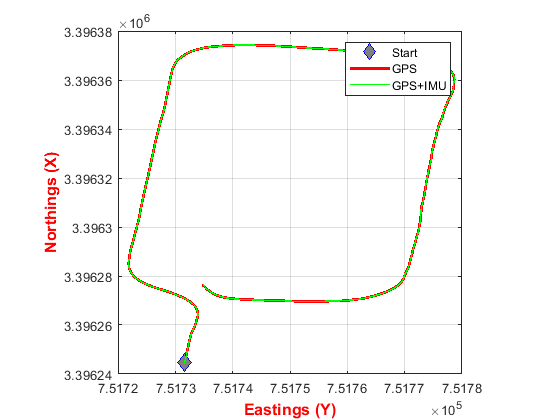

hold on;
q = plot(NEDRPY(:, 2), NEDRPY(:, 1), '-r',...
    'LineWidth',2);
hold on;
plot(NED_estimated(1, 2), NED_estimated(1, 1), 'd', 'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5]);
hold on;
r = plot(NED_estimated(:, 2), NED_estimated(:, 1), '-g',...
    'LineWidth',1);
hold off;
axis square;
xlabel('Eastings (Y)', 'FontSize',12,'FontWeight','bold','Color','r');
ylabel('Northings (X)', 'FontSize',12,'FontWeight','bold','Color','r');
grid;
legend([p, q, r], {'Start', 'GPS', 'GPS+IMU'});

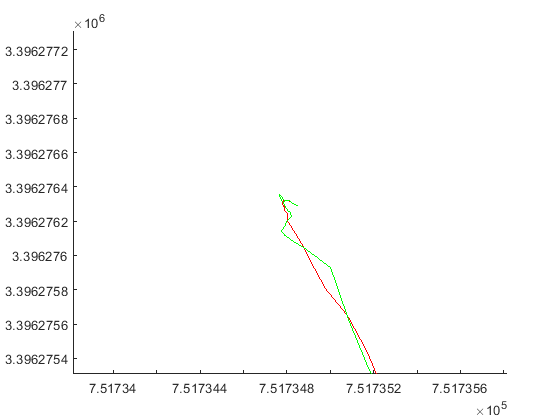

figure(2)
axis square;
clf
clc
%v = VideoWriter('first.avi');
%open(v);
al1 = animatedline('Color', 'r' );
al2 = animatedline('Color','g');
draw_update = 1;
last_num = 1;
for num=1:length(NED_estimated)-1
% for num=1:100
    if draw_update < time_stamp_map(num,2)
        axis([NEDRPY(time_stamp_map(num,2), 2)-1 NEDRPY(time_stamp_map(num,2), 2)+1 ...
            NEDRPY(time_stamp_map(num,2), 1)-1 NEDRPY(time_stamp_map(num,2), 1)+1]);
        draw_update = time_stamp_map(num,2);
        last_num = num;
        addpoints(al1, NEDRPY(time_stamp_map(num,2),2), NEDRPY(time_stamp_map(num,2),1));
        addpoints(al2, NED_estimated(last_num:num,2), NED_estimated(last_num:num,1));
        drawnow
%         writeVideo(v, getframe(gcf));
    end
end

%close(v);
%q = plot(NEDRPY(:, 2), NEDRPY(:, 1), '-r',...
    %'LineWidth',2);
%r = plot(NED_estimated(:, 2), NED_estimated(:, 1), '-g',...
    %'LineWidth',1);

% h = animatedline;
% axis([0,4*pi,-1,1])
% 
% x = linspace(0,4*pi,1000);
% y = sin(x);
% for k = 1:length(x)
%     addpoints(h,x(k),y(k));
%     drawnow
% end



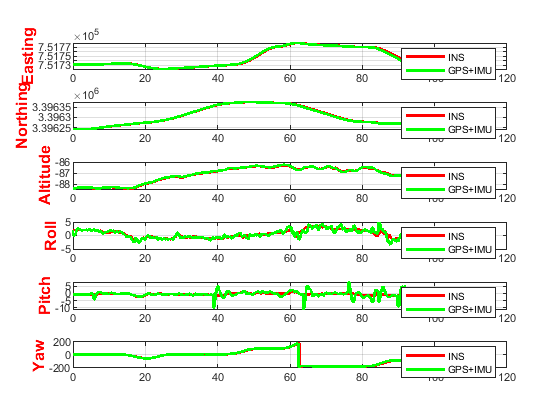

figure(3)
subplot(611)
p = plot(gps(:, 1), NEDRPY(:, 2), '-r',...
    'LineWidth',2);
hold on;
q = plot([gps(1,1);acc_gyro(:, 1)], NED_estimated(:, 2), '-g',...
    'LineWidth',2);
grid;
ylabel('Easting', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

subplot(612)
p = plot(gps(:, 1), NEDRPY(:, 1), '-r',...
    'LineWidth',2);
hold on;
q = plot([gps(1,1);acc_gyro(:, 1)], NED_estimated(:, 1), '-g',...
    'LineWidth',2);
grid;
ylabel('Northing', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

subplot(613)
p = plot(gps(:, 1), NEDRPY(:, 3), '-r',...
    'LineWidth',2);
hold on;
q = plot([gps(1,1);acc_gyro(:, 1)], NED_estimated(:, 3), '-g',...
    'LineWidth',2);
grid;
ylabel('Altitude', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

subplot(614)
p = plot(gps(:, 1), NEDRPY(:, 4)*180/pi, '-r',...
    'LineWidth',2);
hold on;
q = plot([gps(1,1);acc_gyro(:, 1)], RPY_estimated(:, 1)*180/pi, '-g',...
    'LineWidth',2);
grid;
ylabel('Roll', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

subplot(615)
p = plot(gps(:, 1), NEDRPY(:, 5)*180/pi, '-r',...
    'LineWidth',2);
hold on;
q = plot([gps(1,1);acc_gyro(:, 1)], RPY_estimated(:, 2)*180/pi, '-g',...
    'LineWidth',2);
grid;
ylabel('Pitch', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

subplot(616)
p = plot(gps(:, 1), NEDRPY(:, 6)*180/pi, '-r',...
    'LineWidth',2);
hold on;
q = plot([gps(1,1);acc_gyro(:, 1)], RPY_estimated(:, 3)*180/pi, '-g',...
    'LineWidth',2);
grid;
ylabel('Yaw', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

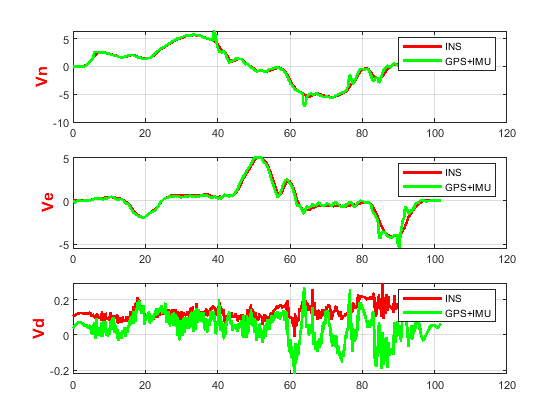

figure(4)
subplot(311)
p = plot(gps(:, 1), velocity(:, 2), '-r',...
    'LineWidth',2);
hold on;
q = plot([acc_gyro(:, 1)], VNED_estimated(:, 1), '-g',...
    'LineWidth',2);
grid;
ylabel('Vn', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

subplot(312)
p = plot(gps(:, 1), velocity(:, 3), '-r',...
    'LineWidth',2);
hold on;
q = plot([acc_gyro(:, 1)], VNED_estimated(:, 2), '-g',...
    'LineWidth',2);
grid;
ylabel('Ve', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})

subplot(313)
p = plot(gps(:, 1), velocity(:, 4), '-r',...
    'LineWidth',2);
hold on;
q = plot([acc_gyro(:, 1)], VNED_estimated(:, 3), '-g',...
    'LineWidth',2);
grid;
ylabel('Vd', 'FontSize',12,'FontWeight','bold','Color','r');
hold off;
legend([p, q], {'INS', 'GPS+IMU'})